### Primer entreno con PCA

%% Configuración inicial
clc; clear; close all;
rng(42);

%% 1) Carga y PCA
load('digits.mat');
d_pca = 30;
[~, score] = pca(digits.image');
X = score(:,1:d_pca);
Y = digits.label;

%% 2) One-hot
labels_onehot = full(ind2vec(Y+1,10));
num_samples = size(X, 1);

%% 3) Validación cruzada
K = 5;
cv = cvpartition(Y, 'KFold', K);
accuracies = zeros(K,1);
nets = cell(K,1);
preds = cell(K,1);
trues = cell(K,1);

fprintf('--- Validación cruzada con %d folds ---\n', K);

--- Validación cruzada con 5 folds ---



for k = 1:K
    trainIdx = training(cv, k);
    testIdx  = test(cv, k);

    p.value  = X(trainIdx,:)';
    p.output = labels_onehot(:,trainIdx);
    x        = X(testIdx,:)';
    t.value  = labels_onehot(:,testIdx);

    % Construcción y entrenamiento de la red
    hiddenSizes = ([200]);
    trainFcn    = 'trainscg'; %tambien puede ser trainscg
    net = feedforwardnet(hiddenSizes, trainFcn);
    net.divideFcn = 'dividetrain';
    net.trainParam.epochs = 300;
    net.trainParam.showWindow = false;

    fprintf('Fold %d: entrenando...\n', k);
    [net, ~] = train(net, p.value, p.output);

    % Evaluación
    y = net(x);
    [~, pred]     = max(y,[],1);
    [~, trueLabs] = max(t.value,[],1);
    acc = sum(pred==trueLabs)/numel(trueLabs);

    fprintf('Fold %d: accuracy %.2f%%\n', k, acc*100);

    % Guardar resultados
    accuracies(k) = acc;
    nets{k} = net;
    preds{k} = pred;
    trues{k} = trueLabs;
end

Fold 1: entrenando...


Fold 1: accuracy 94.95%


Fold 2: entrenando...


Fold 2: accuracy 93.75%


Fold 3: entrenando...


Fold 3: accuracy 93.85%


Fold 4: entrenando...


Fold 4: accuracy 94.20%


Fold 5: entrenando...


Fold 5: accuracy 94.75%



%% 4) Resultados globales
mean_acc = mean(accuracies);
fprintf('\nPrecisión media en test (cross-validation): %.2f%%\n', mean_acc*100);


Precisión media en test (cross-validation): 94.30%



[~, bestFold] = max(accuracies);
fprintf('Mejor modelo: fold %d con %.2f%% de precisión\n', ...
    bestFold, accuracies(bestFold)*100);

Mejor modelo: fold 1 con 94.95% de precisión


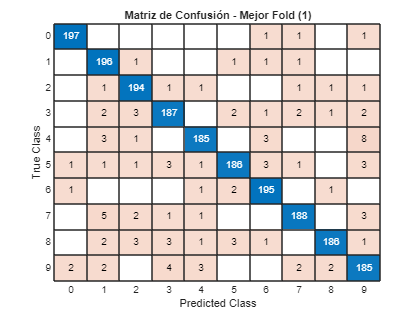


%% 5) Matriz de confusión del mejor modelo
cm = confusionmat(trues{bestFold}-1, preds{bestFold}-1);
figure;
confusionchart(cm, string(0:9));
title(sprintf('Matriz de Confusión - Mejor Fold (%d)', bestFold));

### Añadimos LDA

%% Configuración inicial
clc; clear; close all; clear all;
rng(42);

%% 1) Carga de datos
load('digits.mat');
X = digits.image';           % 10000 x 784
Y = digits.label;            % 10000 x 1

%% 2) PCA
d_pca = 50;
[~, score, ~] = pca(X);
X_pca = score(:,1:d_pca);    % 10000 x d_pca

%% 3) Subclases para LDA
N_subclasses = [1 1 2 2 1 1 1 1 2 2];
X_clustered = [];
Y_clustered = [];
original_labels = [];

for i = 0:9
    idx = find(Y == i);
    X_class = X_pca(idx, :);
    n_sub = N_subclasses(i+1);
    [sub_idx, ~] = kmeans(X_class, n_sub, 'Replicates', 5);

    for j = 1:n_sub
        X_sub = X_class(sub_idx == j, :);
        new_label = i * max(N_subclasses) + j;
        X_clustered = [X_clustered; X_sub];
        Y_clustered = [Y_clustered; repmat(new_label, size(X_sub,1), 1)];
        original_labels = [original_labels; repmat(i, size(X_sub,1), 1)];
    end
end

%% 4) LDA sobre componentes PCA
lda_model = fitcdiscr(X_clustered, Y_clustered, 'DiscrimType', 'pseudoLinear');
class_means = lda_model.Mu';
X_centered = X_clustered - mean(X_clustered);
[U, ~, ~] = svd(class_means - mean(class_means, 2), 'econ');
W_proj = U(:, 1:(numel(unique(Y_clustered)) - 1));
X_final = X_centered * W_proj;
Y_final = original_labels;  % Etiquetas originales (0-9)

%% 5) Codificación one-hot
labels_onehot = full(ind2vec(Y_final(:)' + 1, 10));
num_samples = size(X_final, 1);

%% 6) Validación cruzada
K = 5;
cv = cvpartition(Y_final, 'KFold', K);
accuracies = zeros(K,1);
nets = cell(K,1);
preds = cell(K,1);
trues = cell(K,1);

fprintf('--- Validación cruzada con %d folds ---\n', K);

--- Validación cruzada con 5 folds ---



for k = 1:K
    trainIdx = training(cv, k);
    testIdx  = test(cv, k);

    p.value  = X_final(trainIdx,:)';
    p.output = labels_onehot(:,trainIdx);
    x        = X_final(testIdx,:)';
    t.value  = labels_onehot(:,testIdx);

    % Red neuronal
    hiddenSizes = [200];
    trainFcn    = 'trainscg';
    net = feedforwardnet(hiddenSizes, trainFcn);
    net.divideFcn = 'dividetrain';
    net.trainParam.epochs = 50;
    net.trainParam.showWindow = false;

    fprintf('Fold %d: entrenando...\n', k);
    [net, ~] = train(net, p.value, p.output);

    % Evaluación
    y = net(x);
    [~, pred]     = max(y,[],1);
    [~, trueLabs] = max(t.value,[],1);
    acc = sum(pred==trueLabs)/numel(trueLabs);

    fprintf('Fold %d: accuracy %.2f%%\n', k, acc*100);

    accuracies(k) = acc;
    nets{k} = net;
    preds{k} = pred;
    trues{k} = trueLabs;
end

Fold 1: entrenando...


Fold 1: accuracy 84.45%


Fold 2: entrenando...


Fold 2: accuracy 84.20%


Fold 3: entrenando...


Fold 3: accuracy 86.90%


Fold 4: entrenando...


Fold 4: accuracy 85.05%


Fold 5: entrenando...


Fold 5: accuracy 85.35%



%% 7) Resultados globales
mean_acc = mean(accuracies);
fprintf('\nPrecisión media en test (cross-validation): %.2f%%\n', mean_acc*100);


Precisión media en test (cross-validation): 85.19%



[~, bestFold] = max(accuracies);
fprintf('Mejor modelo: fold %d con %.2f%% de precisión\n', ...
    bestFold, accuracies(bestFold)*100);

Mejor modelo: fold 3 con 86.90% de precisión


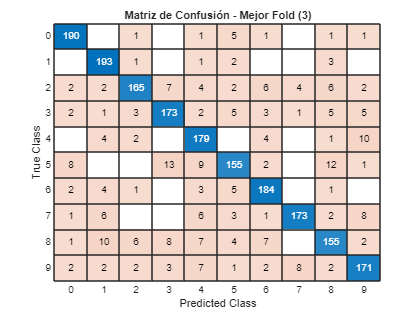


%% 8) Matriz de confusión del mejor modelo
cm = confusionmat(trues{bestFold}-1, preds{bestFold}-1);
figure;
confusionchart(cm, string(0:9));
title(sprintf('Matriz de Confusión - Mejor Fold (%d)', bestFold));

## Algunas comparaciones

### Comparacion training size

%% Configuración inicial
clc; clear; close all;
rng(42);

%% 1) Carga y PCA
load('digits.mat');
d_pca = 50;
[~, score] = pca(digits.image');
X = score(:,1:d_pca);
Y = digits.label;
labels_onehot = full(ind2vec(Y+1,10));
num_samples = size(X, 1);

%% 2) Parámetros
hiddenSizes = [200];
trainFcn = 'trainscg';
epochs = 100;
trainPercents = 0.1:0.1:0.9;
accuracies = zeros(size(trainPercents));
nets = cell(size(trainPercents));
best_preds = cell(size(trainPercents));
best_trues = cell(size(trainPercents));

fprintf('--- Evaluando distintas proporciones de entrenamiento ---\n');

--- Evaluando distintas proporciones de entrenamiento ---



%% 3) Evaluar distintas proporciones de entrenamiento
for i = 1:length(trainPercents)
    pTrain = trainPercents(i);
    nTrain = round(pTrain * num_samples);
    idx = randperm(num_samples);
    trainIdx = idx(1:nTrain);
    testIdx = idx(nTrain+1:end);

    % Preparar datos
    p.value  = X(trainIdx,:)';
    p.output = labels_onehot(:,trainIdx);
    x        = X(testIdx,:)';
    t.value  = labels_onehot(:,testIdx);

    % Red
    net = feedforwardnet(hiddenSizes, trainFcn);
    net.divideFcn = 'dividetrain';
    net.trainParam.epochs = epochs;
    net.trainParam.showWindow = false;

    fprintf('Entrenando con %.0f%% datos de entrenamiento...\n', pTrain*100);
    [net, ~] = train(net, p.value, p.output);

    % Evaluación
    y = net(x);
    [~, pred]     = max(y,[],1);
    [~, trueLabs] = max(t.value,[],1);
    acc = sum(pred==trueLabs)/numel(trueLabs);

    accuracies(i) = acc;
    nets{i} = net;
    best_preds{i} = pred;
    best_trues{i} = trueLabs;

    fprintf('Precisión con %.0f%% de entrenamiento: %.2f%%\n', pTrain*100, acc*100);
end

Entrenando con 10% datos de entrenamiento...


Precisión con 10% de entrenamiento: 86.62%


Entrenando con 20% datos de entrenamiento...


Precisión con 20% de entrenamiento: 90.34%


Entrenando con 30% datos de entrenamiento...


Precisión con 30% de entrenamiento: 89.59%


Entrenando con 40% datos de entrenamiento...


Precisión con 40% de entrenamiento: 91.00%


Entrenando con 50% datos de entrenamiento...


Precisión con 50% de entrenamiento: 91.54%


Entrenando con 60% datos de entrenamiento...


Precisión con 60% de entrenamiento: 91.27%


Entrenando con 70% datos de entrenamiento...


Precisión con 70% de entrenamiento: 90.40%


Entrenando con 80% datos de entrenamiento...


Precisión con 80% de entrenamiento: 92.10%


Entrenando con 90% datos de entrenamiento...


Precisión con 90% de entrenamiento: 91.20%


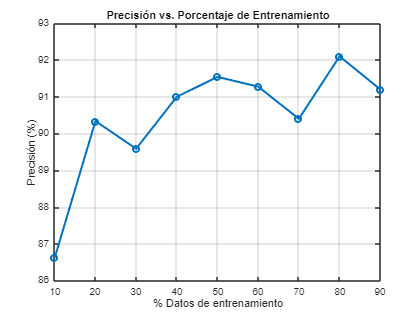


%% 4) Gráfica de resultados
figure;
plot(trainPercents*100, accuracies*100, '-o', 'LineWidth', 2);
xlabel('% Datos de entrenamiento');
ylabel('Precisión (%)');
title('Precisión vs. Porcentaje de Entrenamiento');
grid on;

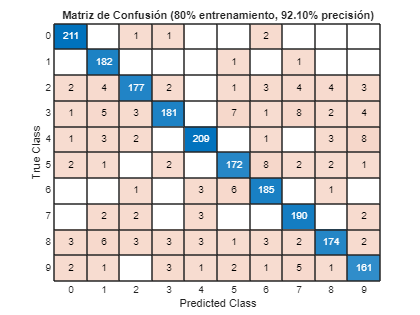


%% 5) Matriz de confusión del mejor modelo
[~, bestIdx] = max(accuracies);
cm = confusionmat(best_trues{bestIdx}-1, best_preds{bestIdx}-1);
figure;
confusionchart(cm, string(0:9));
title(sprintf('Matriz de Confusión (%.0f%% entrenamiento, %.2f%% precisión)', ...
    trainPercents(bestIdx)*100, accuracies(bestIdx)*100));

### Comprobar cuantas dimensiones de PCA es lo mejor y numero neuronas

%% Configuración inicial
clc; clear; close all;
rng(42);

%% Cargar datos
load('digits.mat');
Xraw = digits.image';       % 10000×784
Y    = digits.label;        % 1×10000

%% Configuración
pca_dims = [10 20 50 100 200 500];
hidden_neurons = [10 20 50 100 200 500];
num_dims = length(pca_dims);
num_hidden = length(hidden_neurons);
K = 5;  % Nº de folds para cross-validation

% Accuracy por combinación
acc_norm     = zeros(num_dims, num_hidden);
acc_noNorm   = zeros(num_dims, num_hidden);

%% Entrenamiento con validación cruzada
cv = cvpartition(Y, 'KFold', K);

for norm_mode = 1:2
    if norm_mode == 1
        Xbase = zscore(Xraw);
    else
        Xbase = Xraw;
    end

    for i = 1:num_dims
        d_pca = pca_dims(i);
        [~, score] = pca(Xbase);
        X = score(:,1:d_pca);
        labels_onehot = full(ind2vec(Y+1, 10));

        for j = 1:num_hidden
            hn = hidden_neurons(j);
            acc_folds = zeros(K,1); % accuracy de cada fold

            for fold = 1:K
                trainIdx = training(cv, fold);
                testIdx  = test(cv, fold);

                Xtrain = X(trainIdx,:)';
                Xtest  = X(testIdx,:)';
                Ytrain = labels_onehot(:,trainIdx);
                Ytest  = labels_onehot(:,testIdx);

                net = feedforwardnet(hn, 'trainscg');
                net.divideFcn = 'dividetrain';
                net.trainParam.epochs = 100;
                net.trainParam.showWindow = false;

                net = train(net, Xtrain, Ytrain);

                Ypred = net(Xtest);
                [~, pred] = max(Ypred, [], 1);
                [~, trueLabels] = max(Ytest, [], 1);
                acc_folds(fold) = sum(pred == trueLabels) / numel(trueLabels);
            end

            acc_mean = mean(acc_folds);

            if norm_mode == 1
                acc_norm(i,j) = acc_mean;
            else
                acc_noNorm(i,j) = acc_mean;
            end

            fprintf('Norm: %d | PCA: %3d | Neuronas: %3d | Acc: %.2f%%\n', ...
                norm_mode, d_pca, hn, acc_mean*100);
        end
    end
end

Norm: 1 | PCA:  10 | Neuronas:  10 | Acc: 74.26%
Norm: 1 | PCA:  10 | Neuronas:  20 | Acc: 77.56%
Norm: 1 | PCA:  10 | Neuronas:  50 | Acc: 79.94%
Norm: 1 | PCA:  10 | Neuronas: 100 | Acc: 80.28%
Norm: 1 | PCA:  10 | Neuronas: 200 | Acc: 81.16%
Norm: 1 | PCA:  10 | Neuronas: 500 | Acc: 81.64%
Norm: 1 | PCA:  20 | Neuronas:  10 | Acc: 79.50%
Norm: 1 | PCA:  20 | Neuronas:  20 | Acc: 81.87%
Norm: 1 | PCA:  20 | Neuronas:  50 | Acc: 82.75%
Norm: 1 | PCA:  20 | Neuronas: 100 | Acc: 82.08%
Norm: 1 | PCA:  20 | Neuronas: 200 | Acc: 83.52%
Norm: 1 | PCA:  20 | Neuronas: 500 | Acc: 82.80%
Norm: 1 | PCA:  50 | Neuronas:  10 | Acc: 81.61%
Norm: 1 | PCA:  50 | Neuronas:  20 | Acc: 84.86%
Norm: 1 | PCA:  50 | Neuronas:  50 | Acc: 84.00%
Norm: 1 | PCA:  50 | Neuronas: 100 | Acc: 83.60%
Norm: 1 | PCA:  50 | Neuronas: 200 | Acc: 83.36%
Norm: 1 | PCA:  50 | Neuronas: 500 | Acc: 83.11%
Norm: 1 | PCA: 100 | Neuronas:  10 | Acc: 80.06%
Norm: 1 | PCA: 100 | Neuronas:  20 | Acc: 82.14%
Norm: 1 | PCA: 100 |

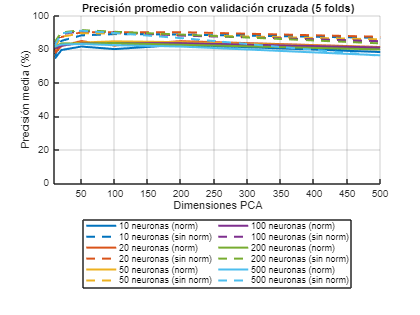


%% Gráfica solicitada
figure;
hold on;
colors = lines(num_hidden); % Paleta de colores para cada tamaño de red

for j = 1:num_hidden
    % Normalizado: línea sólida
    plot(pca_dims, acc_norm(:,j)*100, '-', 'Color', colors(j,:), ...
         'LineWidth', 2, 'DisplayName', sprintf('%d neuronas (norm)', hidden_neurons(j)));
    
    % Sin normalizar: línea discontinua
    plot(pca_dims, acc_noNorm(:,j)*100, '--', 'Color', colors(j,:), ...
         'LineWidth', 2, 'DisplayName', sprintf('%d neuronas (sin norm)', hidden_neurons(j)));
end

xlabel('Dimensiones PCA');
ylabel('Precisión media (%)');
title(sprintf('Precisión promedio con validación cruzada (%d folds)', K));
legend('Location', 'southoutside', 'NumColumns', 2);
grid on;
xlim([min(pca_dims) max(pca_dims)]);
ylim([0 100]);

### Le metemos autoencoder

%% Configuración inicial
clc; clear; close all;
rng(42);

%% 1) Cargar y normalizar
load('digits.mat');
Xraw = digits.image';       % 10000×784
Y    = digits.label;

% Normalizar
Xnorm = zscore(Xraw);       % cada columna con media 0 y var 1

%% 2) PCA inicial a 100 dimensiones
pca_intermediate = 50;
[~, score] = pca(Xnorm);
X_pca = score(:,1:pca_intermediate);   % 10000×100

%% 3) Autoencoder: reducir de 100 → 20
auto_dim = 50;
hiddenSize = auto_dim;

autoenc = trainAutoencoder(X_pca', hiddenSize, ...
    'MaxEpochs', 100, ...
    'L2WeightRegularization', 0.004, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.15, ...
    'ShowProgressWindow', false);

% Codificación comprimida
X_encoded = encode(autoenc, X_pca')';   % 10000×20

%% 4) Preparar etiquetas y dividir
labels_onehot = full(ind2vec(Y+1, 10));
num_samples = size(X_encoded,1);
idx = randperm(num_samples);
nTrain = round(0.8 * num_samples);
trainIdx = idx(1:nTrain);
testIdx  = idx(nTrain+1:end);

p.value  = X_encoded(trainIdx,:)';
p.output = labels_onehot(:,trainIdx);
x        = X_encoded(testIdx,:)';
t.value  = labels_onehot(:,testIdx);

%% 5) Red neuronal MLP
hiddenSizes = [(200)];
trainFcn    = 'trainscg';
net = feedforwardnet(hiddenSizes, trainFcn);
net.divideFcn = 'dividetrain';
net.trainParam.epochs = 100;
net.trainParam.showWindow = false;

% Entrenamiento
[net, tr] = train(net, p.value, p.output);

%% 6) Evaluación
y = net(x);
[~, pred] = max(y, [], 1);
[~, trueLabs] = max(t.value, [], 1);
acc = sum(pred == trueLabs) / numel(trueLabs);
fprintf('Accuracy con PCA→Autoencoder→MLP: %.2f%%\n', acc*100);

Accuracy con PCA→Autoencoder→MLP: 71.10%


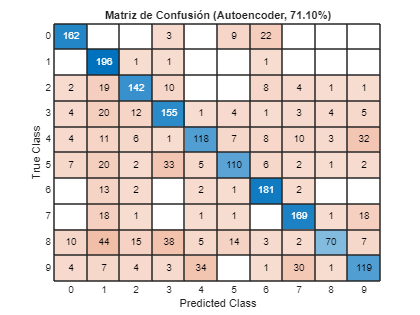


%% 7) Matriz de confusión
cm = confusionmat(trueLabs-1, pred-1);
figure;
confusionchart(cm, string(0:9));
title(sprintf('Matriz de Confusión (Autoencoder, %.2f%%)', acc*100));

# Comprobacion con los datos del profe

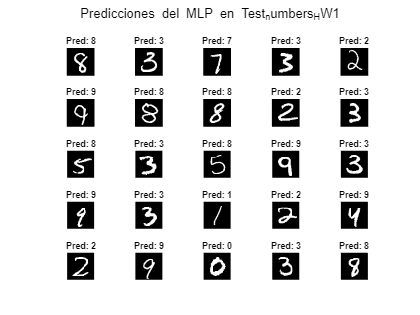

%% Clasificación de Test_numbers_HW1.mat con el mejor MLP (sin normalización)

% Cargar imágenes nuevas no etiquetadas
load('Test_numbers_HW1.mat');  % Debe contener Test_numbers_HW1.image
X_new = Test_numbers.image';  % Cada fila es una imagen (igual que en 'digits.mat')

% Aplicar la misma proyección PCA que se usó para entrenar
[coeff, ~] = pca(digits.image');  % Extraer PCA de nuevo para recuperar 'coeff'
X_new_pca = X_new * coeff(:, 1:d_pca);  % Aplicar proyección PCA

% Clasificar con el mejor modelo entrenado
best_net = nets{bestFold};
Y_pred = best_net(X_new_pca');  % Importante: MLP espera columnas como entrada
[~, predicted_labels] = max(Y_pred, [], 1);
predicted_labels = predicted_labels - 1;  % Ajustar de 1‑based a 0‑based si tus etiquetas son del 0 al 9

% Mostrar algunas imágenes con la predicción
num_to_show = 25;
figure;
for i = 1:num_to_show
    subplot(5, 5, i);
    img = reshape(X_new(i, :), [sqrt(size(X_new,2)), sqrt(size(X_new,2))]);
    imshow(img', []);
    title(['Pred: ', num2str(predicted_labels(i))]);
end
sgtitle('Predicciones del MLP en Test_numbers_HW1');